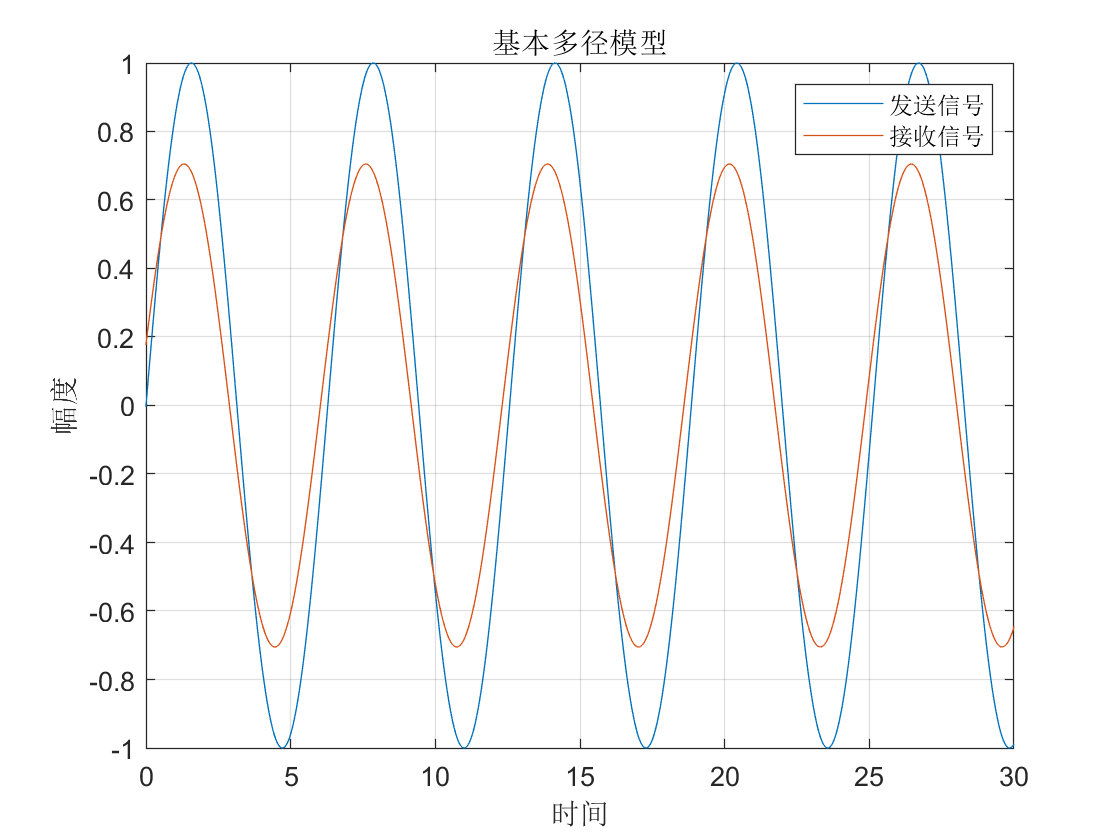

clear;
clc;
TimeStart=-pi;%起始时间
dt=0.01;%采样率
TimeEnd=10*pi;%终止时间
t=TimeStart:dt:TimeEnd;

distance1=500;%第一个障碍物多出的距离为500m
distance2=1500;%第二个障碍物多出的距离为1500m
v_sound=340;%声音的传播速度340m/s
v_wave=3*10^8;%电磁波传播速度

alpha1=0.8;%第一条信道衰减系数
alpha2=0.3;%第二条信道衰减系数
alpha3=0.5;%第三条信道衰减系数

%f1=sin(t)为标准正弦函数
figure;
plot(t,f1(t));
hold on;
f=alpha1*f1(t)+alpha2*f1(t-distance1/v_sound)+alpha3*f1(t-distance2/v_sound);%响应表达式
plot(t,f);

xlim([0, 30]);
ylim([-1.00 1.00]);
xlabel('时间');
ylabel('幅度');
grid on;
title('基本多径模型');
legend('发送信号','接收信号');